# Magnetometer Plot

Author - Daniel Pearson

Version - 11/19/2023

## Introduction

The purpose of this script is to provide calibration data from the MMC5983 on Polaris V2.2 to be used in the orientation Extended Kalman Filter.

Magnetometers on their own provide little to know information about the system but can be a massive help in correcting error generated by the quaternion integration of the EKF prediction step.

## Method

This script will read data logged to a CSV file, filter and fit the data to an idealized system in order to provide the hard and soft data matrices to calibrate the system.

clear variables; close all; clc;

## Read CSV Data

csvLog = readtable('./magCalibration.csv');

magX = csvLog.magX;
magY = csvLog.magY;
magZ = csvLog.magZ;

% magX = ((csvLog.magX - 135594) / 135594) * 800;
% magY = ((csvLog.magY - 134286) / 134286) * 800;
% magZ = ((csvLog.magZ - 138874) / 138874) * 800;

## Apply Butterworth Filter

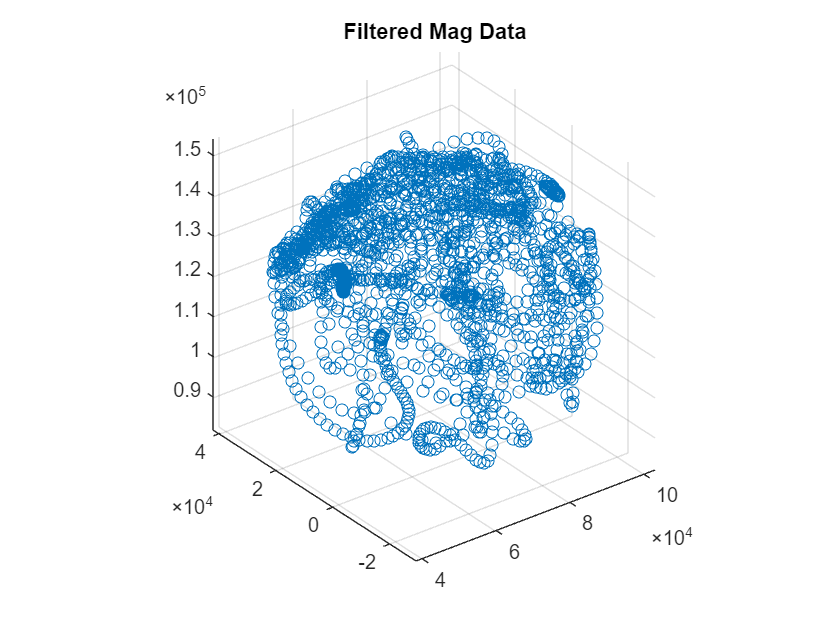

order = 4; % Filter Order
cutoffFreq = 0.1; % [Hz] Cutoff Frequency
[b_filt,a_filt] = butter(order, cutoffFreq);

filtered_magX = filtfilt(b_filt,a_filt, magX);
filtered_magY = filtfilt(b_filt,a_filt, magY);
filtered_magZ = filtfilt(b_filt,a_filt, magZ);

% filtered_magEKFX = filtfilt(b_filt,a_filt, csvLog.MagCalX);
% filtered_magEKFY = filtfilt(b_filt,a_filt, csvLog.MagCalY);
% filtered_magEKFZ = filtfilt(b_filt,a_filt, csvLog.MagCalZ);

scatter3(filtered_magX, filtered_magY, filtered_magZ);
axis equal;
title('Filtered Mag Data');


% scatter3(filtered_magEKFX, filtered_magEKFY, filtered_magEKFZ);
% axis equal;
% title('EKF Mag Data');
% xlabel('Mag X');
% ylabel('Mag Y');
% zlabel('Mag Z');

## Apply Magnetometer Calibration

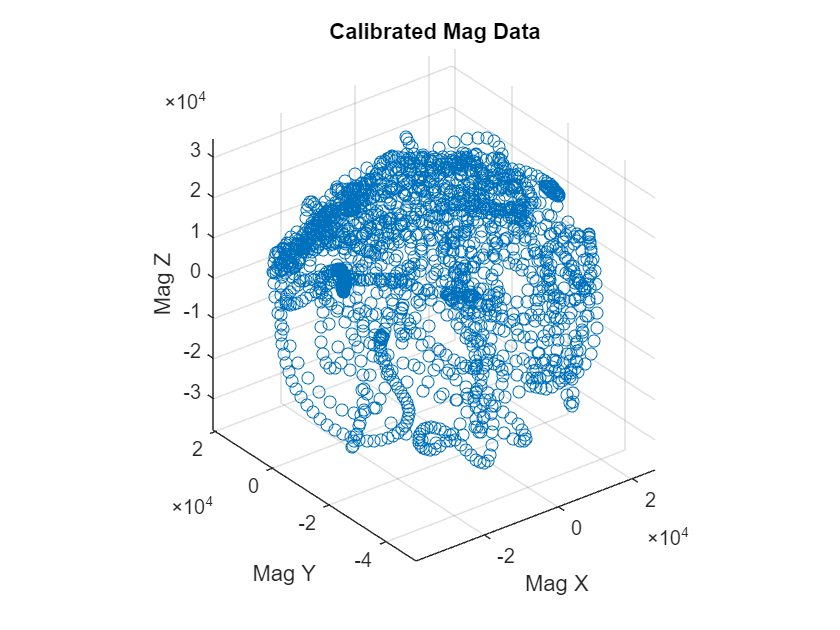

biasX = mean(filtered_magX);
biasY = mean(filtered_magY);
biasZ = mean(filtered_magZ);

calX = filtered_magX - biasX;
calY = filtered_magY - biasY;
calZ = filtered_magZ - biasZ;

calibratedData = [calX'; calY'; calZ'];

scatter3(calibratedData(1,:), calibratedData(2,:), calibratedData(3,:));
axis equal;
title('Calibrated Mag Data');
xlabel('Mag X');
ylabel('Mag Y');
zlabel('Mag Z');

## Fit Ellipsoid to Data Using LSQ

Here we will use an ellipsoid to fit to the magnetometer data in order to try and calculate the hard and soft calibration data later on.

Where an ellipsoid = $\frac{X^2}{a}+\frac{Y^2}{b}+\frac{Z^2}{c}$

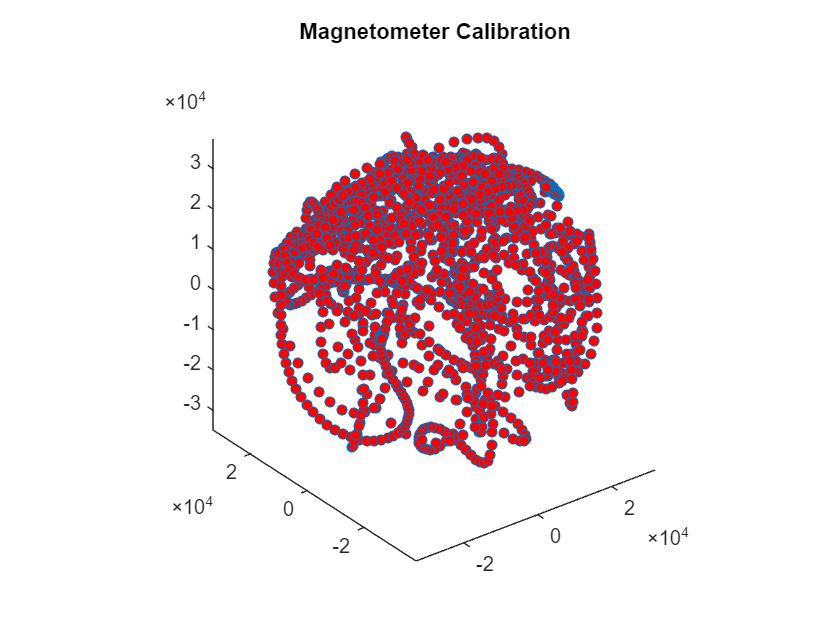

D = [filtered_magX';filtered_magY';filtered_magZ']';

[A,b, expmfs] = magcal(D);

C = (D-b)*A;
plot3(C(:,1),C(:,2),C(:,3),"LineStyle","none","Marker","o","MarkerSize",5,"MarkerFaceColor","r")
axis equal
title('Magnetometer Calibration');

% observedData = [calX'; calY'; calZ']';
% % Make an initial guess for the constants [a;b;c]
% %% LOL wouldn't it be funny if it was just 1,1,1 the whole time 👀
% initialGuess = [1;1;1];
% 
% calibration_params = lsqnonlin(@(params) ellipsoid_residuals(params, observedData), [1; 1; 1]);
% 
% % Extract the optimized parameters
% a_opt = calibration_params(1);
% b_opt = calibration_params(2);
% c_opt = calibration_params(3);
% 
% % Create a range of theta values
% theta = linspace(0, 2*pi, 100);
% phi = linspace(0, pi, 50);
% 
% % Parametric equations for the ellipse
% X_ellipse = sqrt(-1*c_opt) * sin(phi)' * cos(theta);
% Y_ellipse = sqrt(b_opt) * sin(phi)' * sin(theta);
% Z_ellipse = sqrt(a_opt) * cos(phi)' * ones(size(theta));
% 
% % Plot the 3D ellipse with transparency
% surf(X_ellipse, Y_ellipse, Z_ellipse, 'EdgeColor', 'none', 'FaceAlpha', 0.5);
% title('Optimized 3D Ellipse');
% xlabel('X');
% ylabel('Y');
% zlabel('Z');
% grid on;
% axis equal;

function residuals = ellipsoid_residuals(params, data)
    a = params(1);
    b = params(2);
    c = params(3);

    x = data(1, :);
    y = data(2, :);
    z = data(3, :);

    residuals = x.^2/(a^2) + y.^2/(b^2) + (z.^2/c^2) - 1;
end